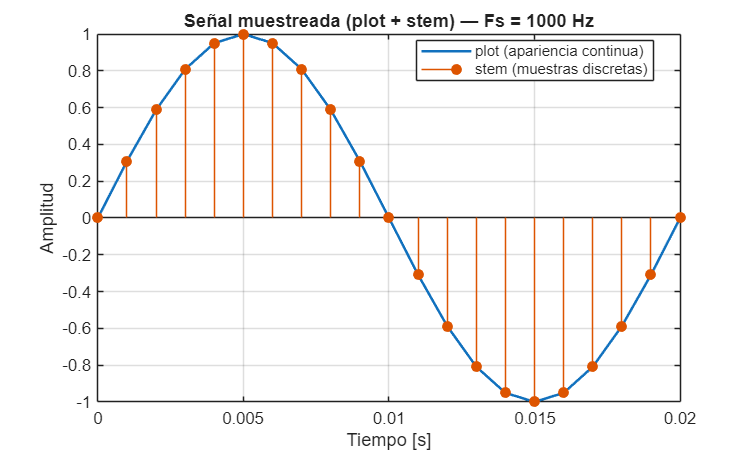

%% Señal muestreada: representación combinada (plot + stem)
%% Autor: Lucas Novales y Javier Matanza
% Parámetros
Fs  = 500;               % Frecuencia de muestreo [Hz]
Ts  = 1/Fs;               % Periodo de muestreo [s]
f0  = 50;
% Amplitud y fase% Frecuencia de la señal [Hz]
A   = 1; 
phi = 0; 
T0 = 1 / f0;

T   = 1; 
% Duración (1 segundo)
t   = 0:Ts:T;         

% Señal muestreada
x = A * sin(2*pi*f0*t + phi);

% Figura grande
figure('Position',[100 100 1000 600]);

% Representación combinada
plot(t, x, 'LineWidth', 1.5); hold on;
stem(t, x, 'filled');
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(sprintf('Señal muestreada (plot + stem) — Fs = %.0f Hz', Fs));
legend('plot (apariencia continua)','stem (muestras discretas)','Location','best');
xlim([0, T0]);